# **Script comparing performance of the old style (@coneMosaicHex-based) to the new style (@cMosaic-based) cone mosaic**

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2022*

# **Step 1.** Generate treeshrew optics

theOI = oiTreeShrewCreate('pupilDiameterMM', 2.0);
micronsPerDegree = theOI.optics.micronsPerDegree;

# **Step 2.** Generate new- and old-style tree shrew cone mosaics

% Old way of generating a @coneMosaicHex for the threeshrew
theOldStyleTreeShrewConeMosaic = coneMosaicTreeShrewCreate(micronsPerDegree);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 369
Scones after making an S-cone free central patch: 369 (added Lcones:0, added Mcones:0)
Scones after pass 1: 218 (added Lcones:205, added Mcones:0)
Scones after pass 2: 128 (added Lcones:120, added Mcones:0)
Scones after pass 3: 74 (added Lcones:66, added Mcones:0)
Scones after pass 4: 48 (added Lcones:31, added Mcones:0)
Scones after pass 5: 40 (added Lcones:9, added Mcones:0)
Scones after pass 6: 40 (added Lcones:0, added Mcones:0)



% New way of generating a @cMosaic for the treeshrew
theNewStyleTreeShrewConeMosaic = cMosaicTreeShrewCreate();


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 369
Scones after making an S-cone free central patch: 369 (added Lcones:0, added Mcones:0)
Scones after pass 1: 221 (added Lcones:198, added Mcones:0)
Scones after pass 2: 132 (added Lcones:123, added Mcones:0)
Scones after pass 3: 76 (added Lcones:73, added Mcones:0)
Scones after pass 4: 49 (added Lcones:28, added Mcones:0)
Scones after pass 5: 42 (added Lcones:8, added Mcones:0)
Scones after pass 6: 42 (added Lcones:0, added Mcones:0)
Achieved cone densities: L (0.943), M (0.000), S (0.057), K (0.000)


# **Step 3. Display the 2 mosaics**

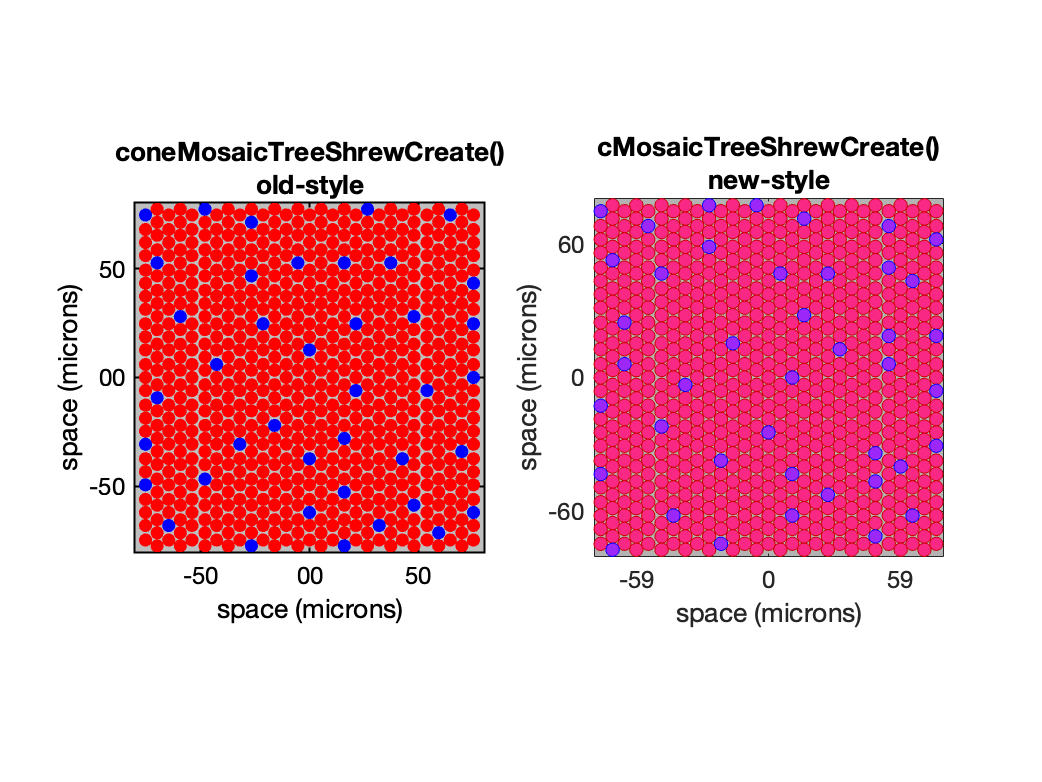

% Display the old and the new cone mosaics
hFig = figure(1);
ax = subplot(1,2,1);
theOldStyleTreeShrewConeMosaic.visualizeGrid(...
    'axesHandle', ax, ...
    'ticksInMicrons', true, ...
    'visualizedConeAperture',  'lightCollectingArea', ...
    'plotTitle', sprintf('coneMosaicTreeShrewCreate()\nold-style'));
set(ax,'fontSize', 12);
  

ax = subplot(1,2,2);
theNewStyleTreeShrewConeMosaic.visualize(...
    'figureHandle', hFig, ...
    'axesHandle', ax, ...
    'domain', 'microns', ...
    'visualizedConeAperture',  'lightCollectingArea', ...
    'plotTitle', sprintf('cMosaicTreeShrewCreate()\nnew-style'), ...
    'fontSize', 12);

# **Step 4.** Compute the optical image for a uniform field, equal photon scene

% Generate uniform field scene
pixelsNum = 512;
    
uniformScene = sceneCreate('uniformEqualPhoton', pixelsNum);
uniformScene = sceneSet(uniformScene, 'wAngular', fovDegs);

% Generate the tree-shrew optical image
theOI = oiCompute(uniformScene, theOI);

# **Step 5.** Compute 256 response instances with the old- and the new-style cone mosaics

% Generate 256 response instances
nTrialsNum = 256;
emPath = zeros(nTrialsNum, 1, 2);

% Compute the cone mosaic activation
t1 = clock();
[~,theCMosaicActivationInstances] = theNewStyleTreeShrewConeMosaic.compute(...
    theOI, 'nTrials', nTrialsNum); 
t2 = clock();
newStyleComputeTime = etime(t2,t1);


t1 = clock();
theConeMosaicHexActivationInstances = theOldStyleTreeShrewConeMosaic.compute(...
    theOI, 'emPath', emPath); 
t2 = clock();
oldStyleComputeTime = etime(t2,t1);


# **Step 6.** Compare performance and results

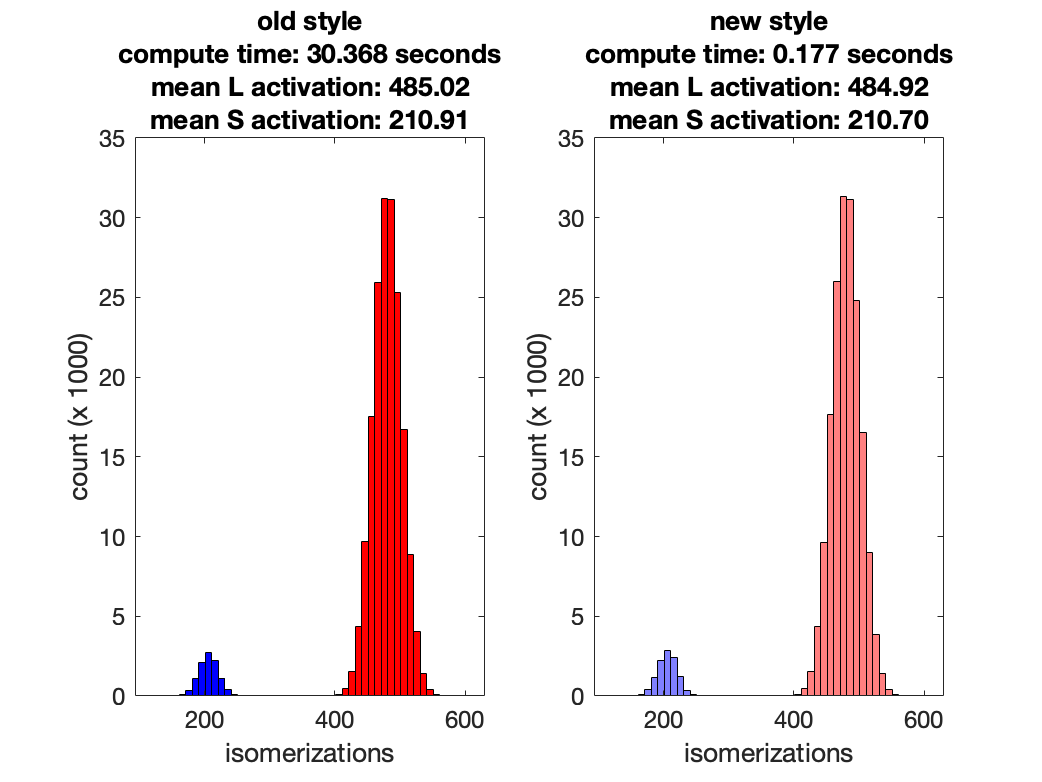

% Retrieve the new-style cone mosaic responses
% L-cone response instances 
theCMosaicLconeActivations = ...
    squeeze(theCMosaicActivationInstances(:, 1, theNewStyleTreeShrewConeMosaic.lConeIndices));
% M-cone response instances
theCMosaicSconeActivations = ...
    squeeze(theCMosaicActivationInstances(:, 1, theNewStyleTreeShrewConeMosaic.sConeIndices));


% Retrieve the old-style cone mosaic responses
lConeIndices = find(theOldStyleTreeShrewConeMosaic.pattern == 2);
sConeIndices = find(theOldStyleTreeShrewConeMosaic.pattern == 4);
theConeMosaicHexLconeActivations = zeros(nTrialsNum, numel(lConeIndices));
theConeMosaicHexSconeActivations = zeros(nTrialsNum, numel(sConeIndices));

for i = 1:nTrialsNum
    theActivation = squeeze(theConeMosaicHexActivationInstances(i,:,:));
    theConeMosaicHexLconeActivations(i,:) = theActivation(lConeIndices);
    theConeMosaicHexSconeActivations(i,:) = theActivation(sConeIndices);
end

% Plot histograms of the L- and S-cone responses for the old- and the new-
% style cone mosaics
bins = (min(theCMosaicActivationInstances(:))-50):10:(max(theCMosaicActivationInstances(:))+50);
nL = histcounts(theConeMosaicHexLconeActivations(:), bins);
nS = histcounts(theConeMosaicHexSconeActivations(:), bins);

hFig = figure(2); clf;
ax = subplot(1,2,1);
bar(ax, bins(1:end-1), nL(:)/1000, 1, 'FaceColor',[1 0. 0.]);
hold(ax, 'on');
bar(ax, bins(1:end-1), nS(:)/1000, 1, 'FaceColor', [0. 0. 1]);
set(ax, 'FontSize', 12);
title(ax, sprintf('old style\ncompute time: %2.3f seconds\nmean L activation: %2.2f\nmean S activation: %2.2f', ...
    oldStyleComputeTime, mean(theConeMosaicHexLconeActivations(:)), mean(theConeMosaicHexSconeActivations(:))));
xlabel(ax, 'isomerizations');
ylabel(ax, 'count (x 1000)');


nL = histcounts(theCMosaicLconeActivations(:), bins);
nS = histcounts(theCMosaicSconeActivations(:), bins);

ax = subplot(1,2,2);
bar(ax, bins(1:end-1), nL(:)/1000, 1, 'FaceColor',[1 0.5 0.5]);
hold(ax, 'on');
bar(ax, bins(1:end-1), nS(:)/1000, 1, 'FaceColor', [0.5 0.5 1]);
set(ax, 'FontSize', 12);
title(ax, sprintf('new style\ncompute time: %2.3f seconds\nmean L activation: %2.2f\nmean S activation: %2.2f', ...
    newStyleComputeTime, mean(theCMosaicLconeActivations(:)), mean(theCMosaicSconeActivations(:))));
xlabel(ax, 'isomerizations');
ylabel(ax, 'count (x 1000)');